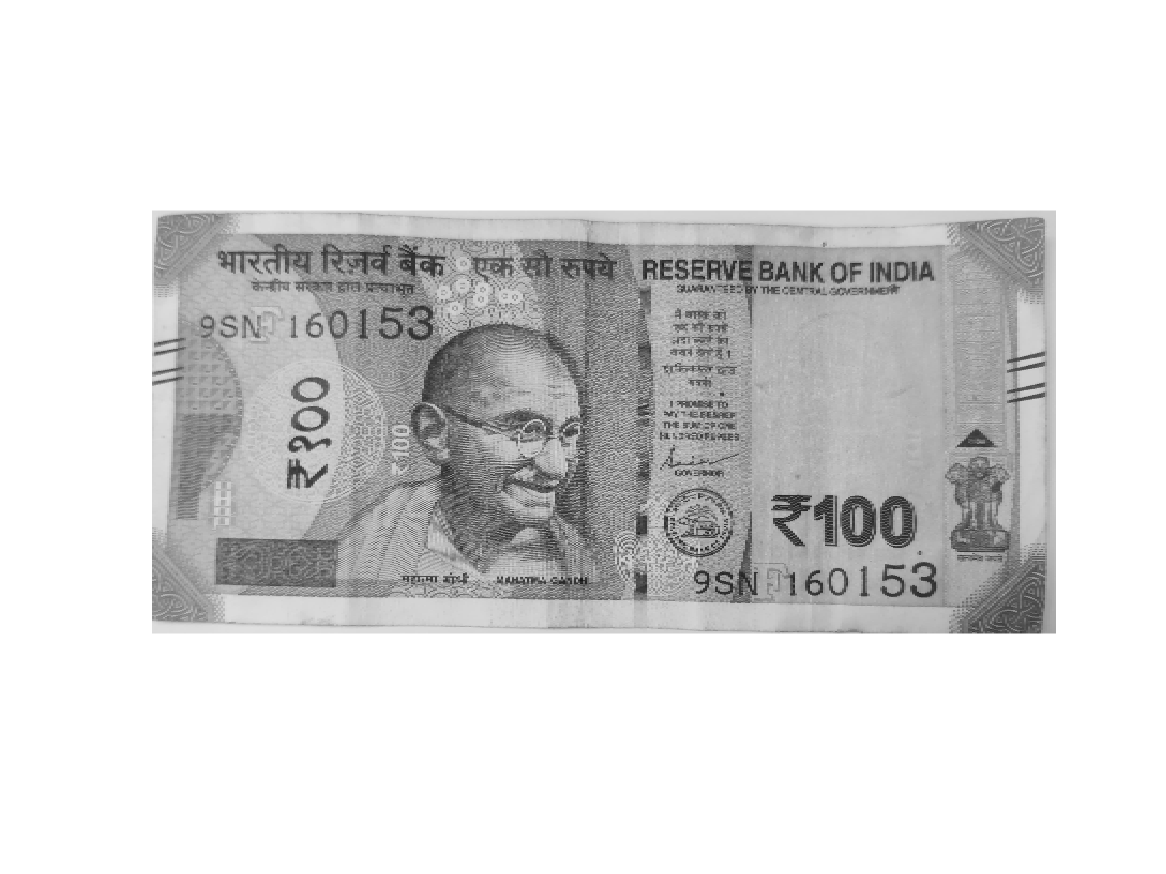

% Read the input grayscale image
grayImage = imread('100_note.jpeg'); % Replace with your grayscale image file
if size(grayImage, 3) == 3
    grayImage = rgb2gray(grayImage); % Convert to grayscale if the image is RGB
end
imshow(grayImage);

Histogram Equalization

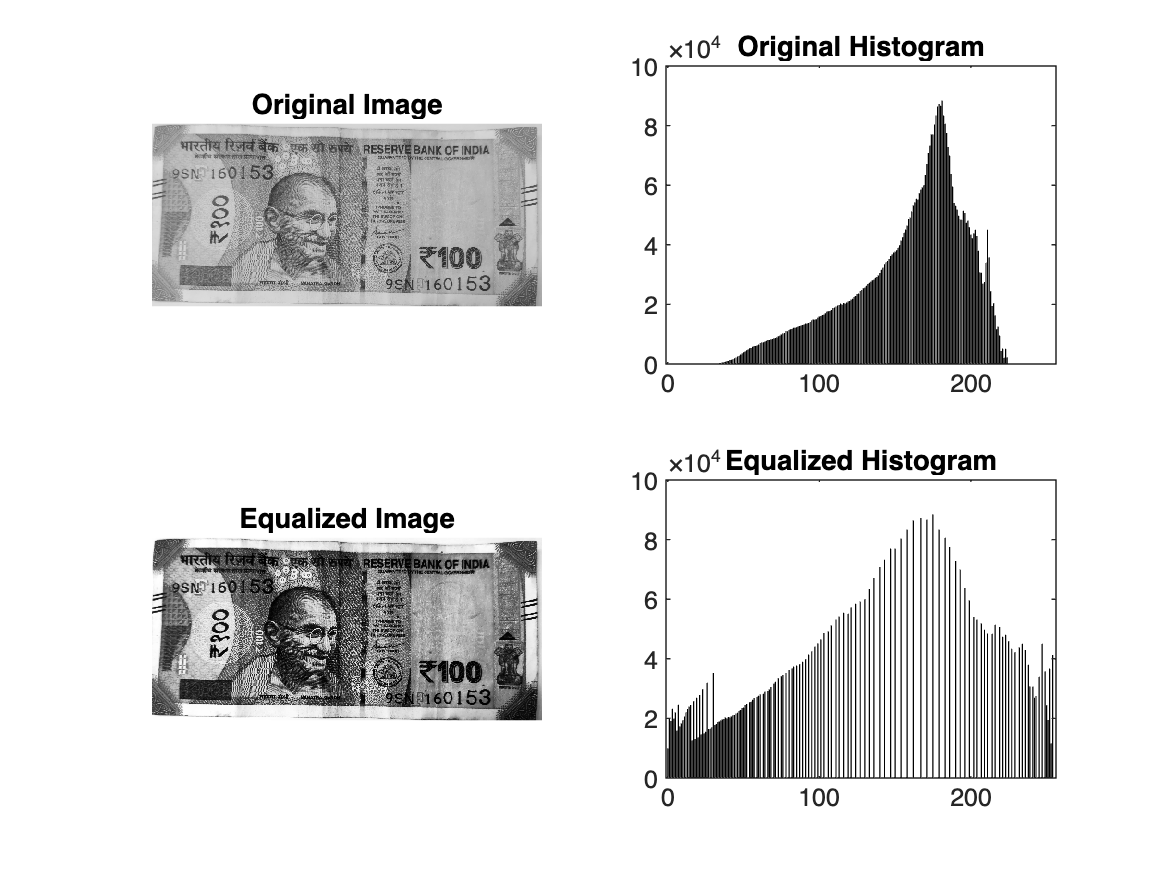


% Get the dimensions of the image
[rows, cols] = size(grayImage);
numPixels = rows * cols;

% Step 1: Calculate the histogram manually
histogram = zeros(1, 256); % Initialize the histogram array
for i = 1:rows
    for j = 1:cols
        intensity = grayImage(i, j); % Get pixel intensity
        histogram(intensity + 1) = histogram(intensity + 1) + 1; % Increment the count
    end
end

% Step 2: Calculate the cumulative distribution function (CDF)
cdf = cumsum(histogram);
cdf_min = min(cdf(cdf > 0)); % Minimum non-zero value of CDF

% Step 3: Normalize the CDF to the range [0, 255]
equalizedLUT = round((cdf - cdf_min) / (numPixels - cdf_min) * 255);

% Step 4: Map the original intensities to equalized intensities
equalizedImage = grayImage; % Initialize equalized image
for i = 1:rows
    for j = 1:cols
        equalizedImage(i, j) = equalizedLUT(grayImage(i, j) + 1);
    end
end

% Display the results
figure;
subplot(2, 2, 1);
imshow(grayImage);
title('Original Image');

subplot(2, 2, 2);
bar(0:255, histogram, 'k');
title('Original Histogram');

subplot(2, 2, 3);
imshow(equalizedImage);
title('Equalized Image');

subplot(2, 2, 4);
newHistogram = zeros(1, 256);
for i = 1:rows
    for j = 1:cols
        newHistogram(equalizedImage(i, j) + 1) = newHistogram(equalizedImage(i, j) + 1) + 1;
    end
end
bar(0:255, newHistogram, 'k');
title('Equalized Histogram');